# Assignment 2: Finite Difference Method

% Connor Warden
% 101078296

## Setup 

The top level script handles setting up the conditions for each simulation to run. Variables are defined and set as input arguments for the solution function to run, with all plots generated upon completion.

The values of length and width are defined at the start of the program and can be altered to change the dimensions of all simulations. The set ratio is (W/L) = (3/2), only nx needs to be changed tochanging nx to keep the ratio of the two consistent

clc;close all;
nx = 75;        % Length
ny = nx*(2/3);  % Width
v_0 = 1;

Variable d controls the section of the assignment that is performed. This can be changed to perform 1B when d is set to 'B'.

d = 'A'; % if set to 'A' then 1A is performed

Boundary conditions change for each simulation, and can be set here prior to running the program. The conditions for part 1A are as follows:

%% Left 1V, right 0V, top/bottom insulating conditions
left_b = v_0; % at x = 0, left
right_b = 0; % at x = L (max x), right. 
% bottom/top not needed for this simulation, will not effect results.
bot_b = 0; % at y = 0, bottom 
top_b = 0; % at y = max_y, top

This changes for 1B to the conditions shown below.

%% Right/left 1V, top/bottom 0V 
% left_b = v_0; % at x = 0, left
% right_b = v_0; % at x = L (max x), right. 
% bot_b = 0; % at y = 0, bottom 
% top_b = 0; % at y = max_y, top

Now the program is ready run, using the following function call. Sol returns the matrix vmap which contains the potential for each simulation, and then it is plotted using the surf function

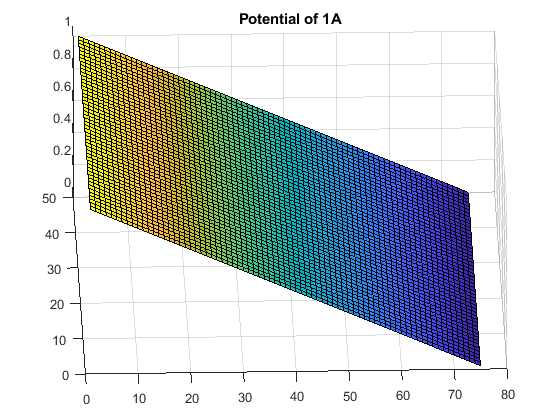

[vmap] = sol(nx, ny, left_b, right_b, bot_b, top_b, d);
figure(1)
surf(vmap');
title("Potential of 1A")
view([-1.687 47.699])

The following lines were added in case the user would like to see all of plots for part 1 at the same time. 

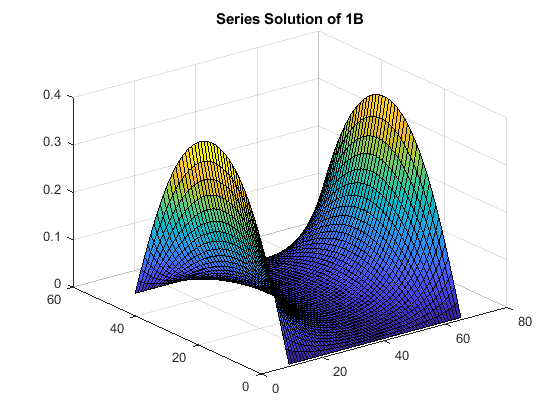

%% Uncomment the following 5 lines if 1A and 1B would like to be seen simultaneously.
right_b = v_0;
d = 'B';
[vmap] = sol(nx, ny, left_b, right_b, bot_b, top_b, d);

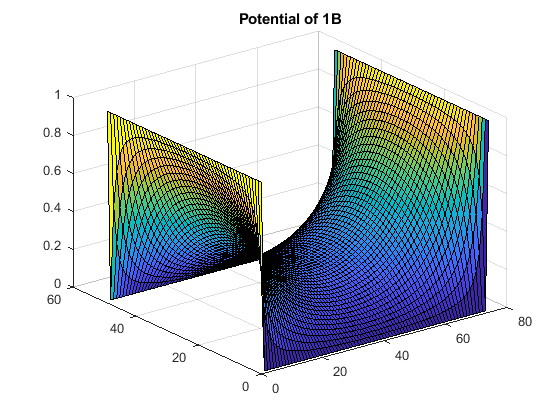

figure(3)
surf(vmap')
title("Potential of 1B")

Finally, part 2 is implemented using its own function called sol_2. sol_2 plots all of its own functions so no additional figure calls are needed.

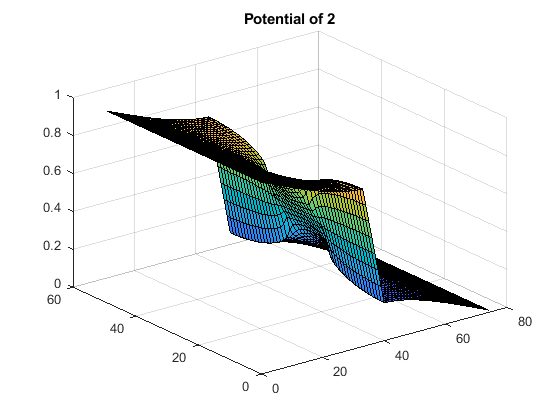

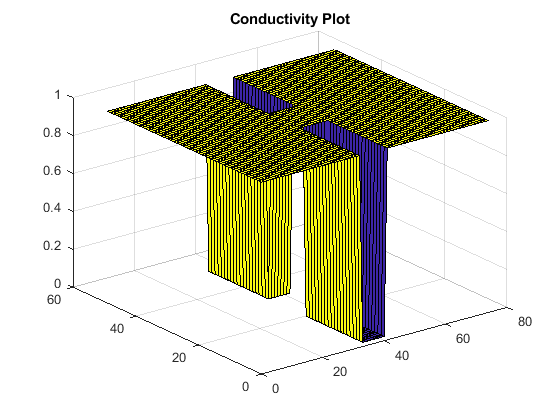

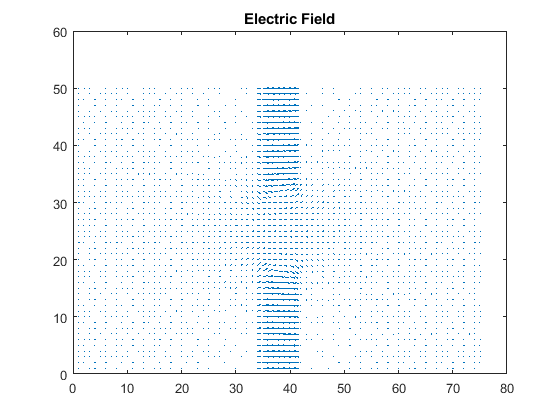

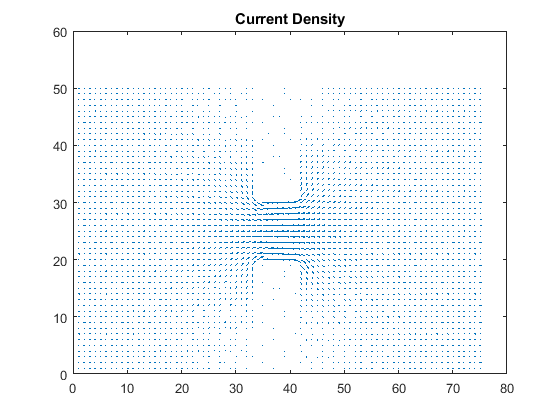

sol_2(nx,ny);

## Solution Functions

#### Part 1

sol makes use of the input variable given to generate multiple plots representing the electric potential of each given case. Inputs include the dimensions, boundaries, and simulation type.

function [vmap] = sol(nx,ny,left_b, right_b, bot_b, top_b, d)
%% Inputs
% nx = length of region
% ny = height of region
% left_b = left boundary
% right_b = right boundary
% bot_b = bottom boundary
% top_b = top boundary
%% Ouputs
% vmap = potential map

A matrix and vector were created to calculate vmap. These are to be filled with new values pertaining to the input parameters.

g = sparse(nx*ny, nx*ny); % g matrix
f = zeros(nx*ny, 1); % f vector

The following is the main body of code that manipulates g and f. For case 'A' top and bottom are both insulating, meaning they need to take into account the 3 adjacent sides but not themselves. 

if d == 'A'
    for i = 1:(nx)
        for j = 1:(ny)

            n = j + (i-1)*ny;

            if i == 1 % Left side of box      
                g(n,:) = 0;
                g(n,n) = 1;
                f(n) = left_b;
            elseif i == nx % Right side of box
               g(n,:) = 0;
               g(n,n) = 1;
               f(n) = right_b;
             elseif j == 1
                % Takes into account the values above and on both sides
                nxm = j + (i - 2) * ny;
                nxp = j + i*ny;
                nyp = j + 1 + (i - 1) * ny;
    
                g(n, n) = -3; % 3 Sides Considered
                g(n, nxm) = 1;
                g(n, nxp) = 1;
                g(n, nyp) = 1;           
                 
             elseif j == ny % Top of the bpx
                % Takes into account the values below and on both sides
                nxm = j + (i-2)*ny;
                nxp = j + i*ny;
                nym = j-1 + (i-1)*ny;
    
                g(n,n) = -3; % 3 Sides Considered
                g(n, nxm) = 1;
                g(n, nxp) = 1;
                g(n, nym) = 1;
            else
                % Everywhere else takes into account all 4 directions
                nxm = j + (i-2)*ny;
                nxp = j + i*ny;
                nym = j-1 + (i-1)*ny;
                nyp = j+1 + (i-1)*ny;

                g(n,n) = -4; % 4 Sides Considered

                g(n, nxm) = 1;
                g(n, nxp) = 1;
                g(n, nym) = 1;
                g(n, nyp) = 1;
            end
        end    
    end

For case 'B' all boundaries have a set value.

elseif d == 'B'
    for i = 1:(nx)
        for j = 1:(ny)

            n = j + (i-1)*ny;

            if i == 1       
                g(n,:) = 0;
                g(n,n) = 1;
                f(n) = left_b; 
            elseif i == nx
               g(n,:) = 0;
               g(n,n) = 1;
               f(n) = right_b; 
             elseif j == 1
                g(n,:) = 0;
                g(n,n) = 1;      
                f(n) =  bot_b;                 
             elseif j == ny
                g(n,:) = 0;
                g(n,n) = 1;
                f(n) =  top_b;
             else
                nxm = j + (i-2)*ny;
                nxp = j + i*ny;
                nym = j-1 + (i-1)*ny;
                nyp = j+1 + (i-1)*ny;

                g(n,n) = -4;

                g(n, nxm) = 1;
                g(n, nxp) = 1;
                g(n, nym) = 1;
                g(n, nyp) = 1;
            end
        end    
    end
end

v was determined using the now calculated g and f.

v = g\f; % g and f must have the same number of rows
vmap = zeros(nx,ny);
for i = 1:(nx)
    for j = 1:(ny)
        n = j + (i-1) * ny;
        vmap(i, j) = v(n);
    end
end

The following code only applies to part B, and handles the generation of a series solution.

% Part 1(b) Analytical series
if d == 'B'
    v_0 = 1;
    L = 3;
    W = 2;
    a = W;
    b = L;

    % Instead of going to infinity only go to a set number
    itr = 100; % 100 total iterations
    X = linspace(-b, b, nx);
    Y = linspace(0, a, ny);

    for r = 1:ny
        x(r,:) = X;
    end
    for c = 1:nx
        y(:,c) = Y;
    end
    
    soln = zeros(ny, nx);
    for i=1:itr
        n = 2*i - 1;
        soln = soln + (1./n)*((cosh((n.*pi.*x)./a))./(cosh((n.*pi.*b)./a))).*(sin((n.*pi.*y)./a));
    end

    series_soln = ((4.*v_0)./pi)*soln;

    figure(2);
    surf(series_soln);
    title("Series Solution of 1B")
end
end

#### Part 2

sol_2 does the same function as sol, just with the addition of a conducivity map. The conductivity map is needed to define the rectangular regions where there is a different conductivity.

function [] = sol_2(nx,ny)
%% Inputs
% nx = length of region
% ny = height of region

% Potential within rectangular regions
sigma_in = 0.01; 

cMap defines the conductivity of the rectangular regions. Within the bounds set by the if statements the potential is changed to a lower value. The bounds were implementaed as percentages so that they stay consistent despite changes in nx and ny.

cMap = ones(nx,ny);
for i = 1:nx
    for j = 1:ny
        if ((i>nx*0.45) && (i<nx*0.55) && (j<(ny*0.4))) 
            cMap(i,j) = sigma_in;
        elseif ((i>nx*0.45) && (i<nx*0.55) && (j>(ny*0.6)))
            cMap(i,j) = sigma_in;
        end
    end
end

The manipulation of g and f follow the same method as part 1. cMap is implemented to take into account the differing conductivty.

g = sparse(nx*ny); % g matrix
f = zeros(nx*ny, 1); % f vector

for i = 1:(nx)
    for j = 1:(ny)
        
        n = j + (i-1)*ny;
        
        if i == 1       
           g(n,n) = 1;
           f(n) = 1; 
        elseif i == nx
           g(n,n) = 1;
           f(n) = 0; 
        elseif j == 1
           nxm = j + (i - 2) * ny;
           nxp = j + (i) * ny;
           nyp = j + 1 + (i - 1) * ny;

           rxm = (cMap(i, j) + cMap(i - 1, j)) *0.5;
           rxp = (cMap(i, j) + cMap(i + 1, j)) *0.5;
           ryp = (cMap(i, j) + cMap(i, j + 1)) *0.5;

           g(n, n) = -(rxm+rxp+ryp);
           g(n, nxm) = rxm;
           g(n, nxp) = rxp;
           g(n, nyp) = ryp;
             
        elseif j == ny
           nxm = j + (i - 2) * ny;
           nxp = j + (i) * ny;
           nym = j - 1 + (i - 1) * ny;

           rxm = (cMap(i, j) + cMap(i - 1, j)) *0.5;
           rxp = (cMap(i, j) + cMap(i + 1, j)) *0.5;
           rym = (cMap(i, j) + cMap(i, j - 1)) *0.5;

           g(n, n) = -(rxm + rxp + rym);
           g(n, nxm) = rxm;
           g(n, nxp) = rxp;
           g(n, nym) = rym;
        else
           nxm = j + (i-2)*ny;
           nxp = j + (i)*ny;
           nym = j-1 + (i-1)*ny;
           nyp = j+1 + (i-1)*ny;

           rxm = (cMap(i,j) + cMap(i-1,j))*0.5;
           rxp = (cMap(i,j) + cMap(i+1,j))*0.5;
           rym = (cMap(i,j) + cMap(i,j-1))*0.5;
           ryp = (cMap(i,j) + cMap(i,j+1))*0.5;

           g(n,n) = -(rxm+rxp+rym+ryp);
           g(n,nxm) = rxm;
           g(n,nxp) = rxp;
           g(n,nym) = rym;
           g(n,nyp) = ryp;
        end
    end    
end

v = g\f;


vmap = zeros(nx,ny);
for i = 1:(nx)
    for j = 1:(ny)
        n = j + (i-1) * ny;
        vmap(i, j) = v(n);
    end
end

Electric field matrices are generated by manipulating the values of vmap.

for i = 1:(nx)
    for j = 1:(ny)
        if i == 1
            Ex(i,j) = vmap(i+1,j) - vmap(i,j);
        elseif i == nx
            Ex(i,j) = vmap(i,j) - vmap(i-1,j);
        else
            Ex(i,j) = (vmap(i+1,j) - vmap(i-1,j))*(0.5);
        end
        if j == 1
            Ey(i,j) = vmap(i,j+1) - vmap(i,j);
        elseif j == ny
            Ey(i,j) = vmap(i,j) - vmap(i,j-1);
        else
            Ey(i,j) = (vmap(i,j+1) - vmap(i,j-1))*(0.5);
        end
    end
end

Ex = -Ex;
Ey = -Ey;

Current density determined by multiple the electric field by the conductivity.

i_x = cMap .* Ex;
i_y = cMap .* Ey;


figure(4)
surf(vmap')
title("Potential of 2")

figure(5)
surf(cMap')
title("Conductivity Plot")

figure(6)
quiver(Ex', Ey');
title("Electric Field")

figure(7)
quiver(i_x', i_y')
title("Current Density")
end

## Results

#### Part 1A

####  Part 1B

I was unable to obtain a complete series solution due to unknown errors. Debugging was done with the help of a TA and the professor yet the issue was still unable to be resolved. However, it is known that the series solution is the most accurate repesentation of what the graph should look like. Knowing this, and seeing the example series solution from the introduction video I concluded that the larger the number of iteration of series solution, the more accurate the result. As such, it is logical that increasing the mesh density will have a similar result to this, as a denser mesh will cover more 'cases' and result in a more corrent solution.

#### Part 2A

#### Part 2B

      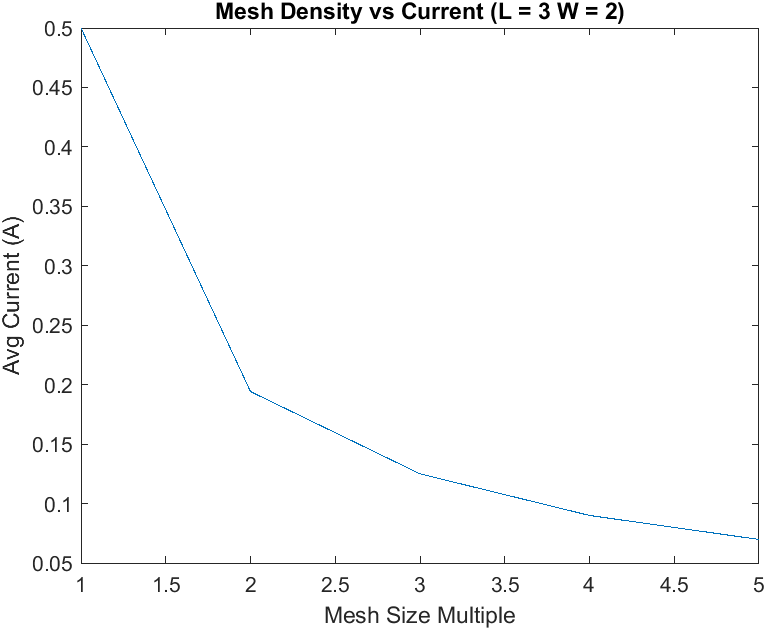

As mesh density was increased the average current decreased until it began to stabilize. This plot was done with a smaller length and width as the larger nx and ny values took a long time to simulate.

#### Part 2C

    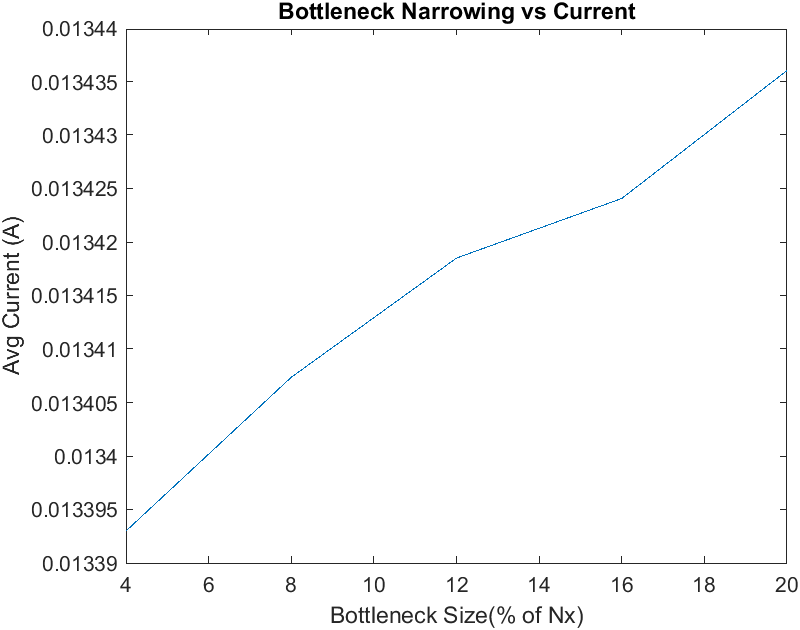

As bottneck decreasde in size, the average current decreased. The larger the bottleneck the larger the average current became.

#### Part 2D

####    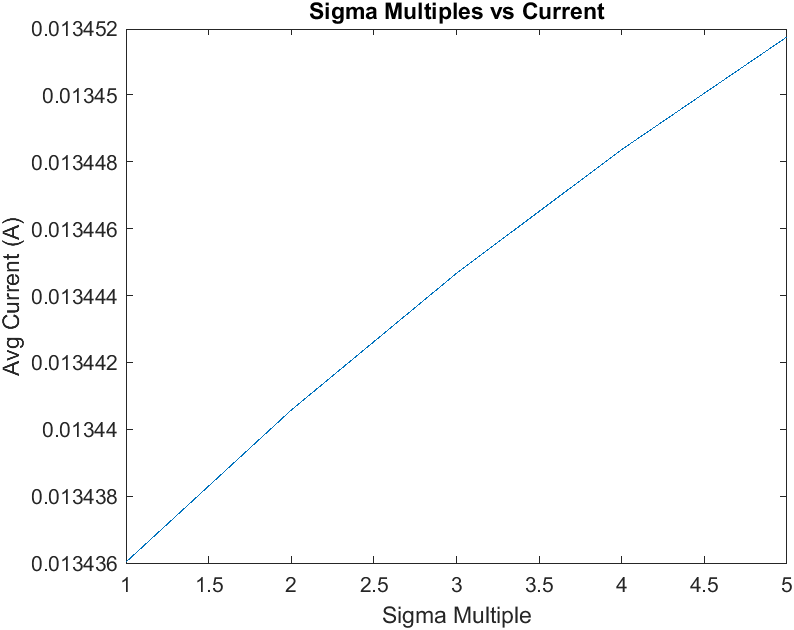

As the value of sigma increased within the boxes, the average current increased.